close all; clear all

## optimization using integral

%settings
%par_true = [0.002 0.027 0.0096 3034e9 153e9 0.4e9]; %wodarz 1
par_true = [0.022 0.015 0.0177 3064e9 58e9 47.5e9]; %wodarz 2

lb = [1e-4 1e-4 1e-5 0.75 0.75 1e1]; lb_sd = [1e5 1e5];
ub = [0.1 0.1 0.5 1.25 1.25 1e12]; ub_sd = [1e13 1e13];


days = 600 ;
%samplesX=0;
samplesX = 10 ;
samplesY = 100;

spacing = 2; % 1 = linear; 2 = log10; 3 = log

sd_noise = [1e9, 3e10, 5e9];

options = optimoptions('lsqnonlin','TolFun',1e-10,'TolX',1e-10);
n_starts = 50;

%construct start (later add multi start)
par_init = [0.001 0.001 0.0005 0 0 1e10]; %start parameters
sdXY = sd_noise; %[1e8 1e8]; %initial guess for noise sd


%meas_f = tdfread(filename); %observableId holds x_t or y_t

## set data

[tspanX] = setSpacing(days, samplesX, spacing);
[tspanY] = setSpacing(days, samplesY, spacing);

%simulated
[x_true, y_true] = intLea(par_true, tspanX, tspanY);

firstnoise = sum(tspanY(:) <= 200);

xnoise = normrnd(0, sd_noise(1), 1, length(x_true));
ynoise = [normrnd(0, sd_noise(2), 1, firstnoise) normrnd(0, sd_noise(3), 1, length(y_true)-firstnoise)];

xdata = x_true + xnoise;
ydata = y_true + ynoise;

for i = 1:(samplesX)
    if xdata(samplesX+1-i) <= 0
        diff = xdata(samplesX+1-i) - 1e4
        
        xdata(samplesX+1-i) = 1e4
        xdata(samplesX - i) = xdata(samplesX - i) + diff  
    end
end

for i = 2:(samplesY-4)
    if ydata(samplesY+1-i) <= 0
        diff = ydata(samplesY+1-i) - 1e4
        
        ydata(samplesY+1-i) = 1e4
        ydata(samplesY - 4 - i) = ydata(samplesY - 4 - i) + diff  %adapt two steps back
    end
end

diff = -6.3785e+07

ydata = 	1.0e+11 *

    0.8922    1.2117    1.7955    1.2808    2.0888    1.2716    2.2028    0.8611    2.0811    1.9353    1.4765    1.8235    2.3292    2.1998    1.3232    2.1751    2.6640    2.3017    2.6140    1.6909    2.1873    2.6998    1.7773    2.4889    2.6117    3.1835    2.7228    2.8026    3.1079    4.5800    4.3364    3.7571    4.0325    4.6392    4.6648    4.1584    4.9768    4.6992    5.0256    5.2164    5.6530    5.9325    6.0896    6.2897    6.0100    6.2353    6.3610    6.1736    6.6965    7.5369


ydata = 	1.0e+11 *

    0.8922    1.2117    1.7955    1.2808    2.0888    1.2716    2.2028    0.8611    2.0811    1.9353    1.4765    1.8235    2.3292    2.1998    1.3232    2.1751    2.6640    2.3017    2.6140    1.6909    2.1873    2.6998    1.7773    2.4889    2.6117    3.1835    2.7228    2.8026    3.1079    4.5800    4.3364    3.7571    4.0325    4.6392    4.6648    4.1584    4.9768    4.6992    5.0256    5.2164    5.6530    5.9325    6.0896    6.2897    6.0100    6.2353    6.3610    6.1736    6.6965    7.5369



%use data information in boundaries for x0 and y0
lb(4) = lb(4) * xdata(1) ; ub(4) = ub(4) * xdata(1); par_init(4) = xdata(1);
lb(5) = lb(5) * ydata(1) ; ub(5) = ub(5) * ydata(1); par_init(5) = ydata(1);

## Get latin hypercube sampled starts

[par_starts,~] = lhsdesign_modified(n_starts,[lb lb_sd],[ub ub_sd]);
startpoints = CustomStartPointSet(par_starts(:,1:6));
startp_llh =  CustomStartPointSet(par_starts);

## optimization for integral

%set inputs for lsqnonlin 
lsqfun = @(par)diff_integral(par,xdata,ydata,tspanX, tspanY);

[par_opt,resnorm] = lsqnonlin(lsqfun, par_init,lb,ub,options);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


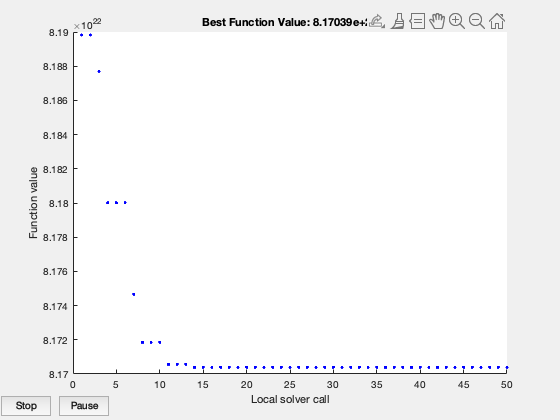

MultiStart completed the runs from all start points.

All 50 local solver runs converged with a positive local solver exit flag.


xmulti = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.0654    0.0745    0.0436


errormulti = 8.1704e+22

exitflag = 1

output = struct with fields:
                funcCount: 15141
         localSolverTotal: 50
       localSolverSuccess: 50
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵All 50 local solver runs converged with a positive local solver exit flag.'


solutions =   1×50 GlobalOptimSolution array with properties:

    X
    Fval
    Exitflag
    Output
    X0




problem = createOptimProblem('lsqnonlin','x0',par_init,'objective',lsqfun,...
    'lb',lb,'ub',ub,'xdata',xdata,'ydata',ydata); %'lsqnonlin'
ms = MultiStart('PlotFcns',@gsplotbestf);
[xmulti,errormulti,exitflag,output,solutions] = run(ms,problem,startpoints)

## optimization using log likelihood

%set inputs for fmincon
par_init = [par_init sdXY(1:2)];

negllh = @(par)negLLH(par,xdata,ydata,tspanX, tspanY);

[par_optfmin,resnormfmin,exitflagfmin, outputfmin] =  ...
    fmincon(negllh,par_init,[],[],[],[],[lb lb_sd],[ub ub_sd]);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


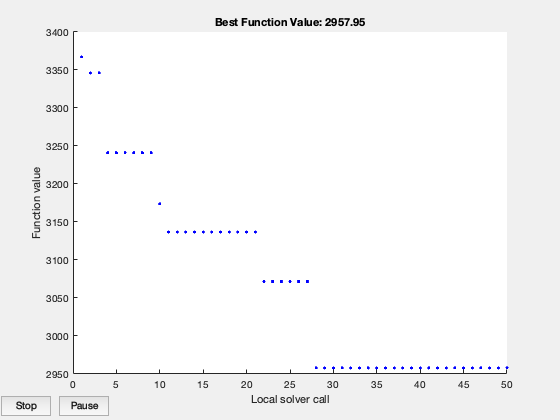

MultiStart completed the runs from all start points.

All 50 local solver runs converged with a positive local solver exit flag.


xmultillh = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


errormultillh = 2.9580e+03

exitflagllh = 1

outputllh = struct with fields:
                funcCount: 23090
         localSolverTotal: 50
       localSolverSuccess: 50
    localSolverIncomplete: 0
    localSolverNoSolution: 0
                  message: 'MultiStart completed the runs from all start points.↵↵All 50 local solver runs converged with a positive local solver exit flag.'


solutionsllh =   1×50 GlobalOptimSolution array with properties:

    X
    Fval
    Exitflag
    Output
    X0



problemllh = createOptimProblem('fmincon','x0',par_init,'objective',negllh,...
    'lb',[lb lb_sd],'ub',[ub ub_sd],'xdata',xdata,'ydata',ydata); 
ms_llh = MultiStart('PlotFcns',@gsplotbestf);
[xmultillh,errormultillh,exitflagllh,outputllh,solutionsllh] = ...
    run(ms_llh,problemllh,startp_llh)

## plot data

xmulti

xmulti = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.0654    0.0745    0.0436


errormulti

errormulti = 8.1704e+22

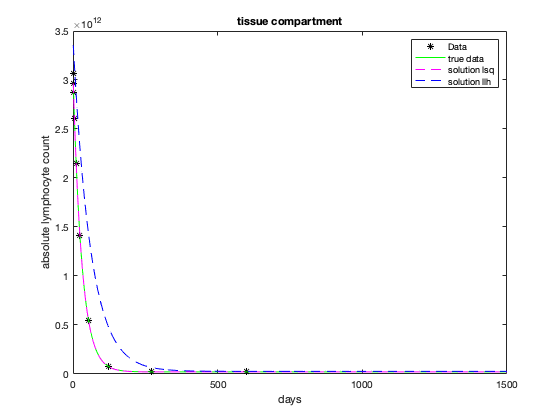


tspan = [1:1:1500];
[x_opt, y_opt] = intLea(xmulti, tspan, tspan);
[x_llh, y_llh] = intLea(xmultillh, tspan, tspan);
[x_true, y_true] = intLea(par_true, tspan, tspan);

figure;

plot(tspanX, xdata, '*k'); hold on;
plot(tspan, x_true, 'g'); hold on;
plot(tspan, x_opt, '--m'); hold on;
plot(tspan, x_llh, '--b'); hold on;

title('tissue compartment')
xlabel('days')
ylabel('absolute lymphocyte count')
legend('Data','true data', 'solution lsq','solution llh')

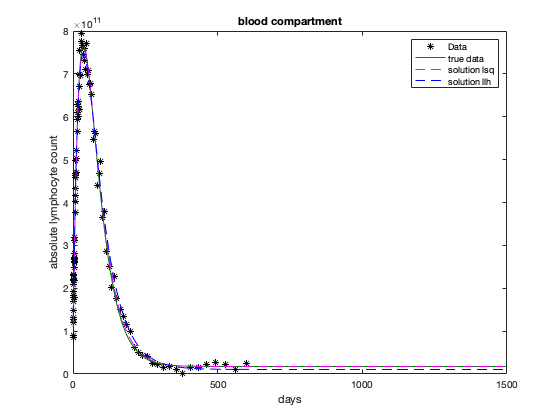


figure;

plot(tspanY, ydata, '*k'); hold on;
plot(tspan, y_true, 'color',[0 0.5 0]); hold on;
plot(tspan, y_opt, '--m'); hold on;
plot(tspan, y_llh, '--b'); hold on;

title('blood compartment')
xlabel('days')
ylabel('absolute lymphocyte count')
legend('Data','true data',  'solution lsq','solution llh')

## Profile Likelihood Analysis

[parval, parres] = Profiles_llh(negllh, xmultillh, 100, [lb lb_sd], [ub ub_sd]);

originalpar = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


par = 	1.0e+12 *

    0.0000    0.0000    0.0000    3.4095    0.0876    0.9584    1.5660    0.1501


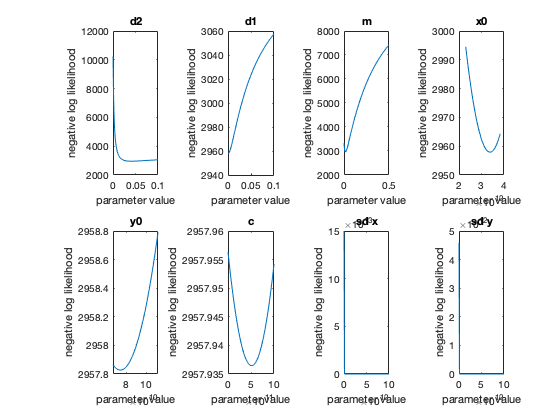



figure;
subplot(2,4,1)
plot(parval(1,:),parres(1,:));xlabel('parameter value');ylabel('negative log likelihood');title('d2');
subplot(2,4,2)
plot(parval(2,:),parres(2,:));xlabel('parameter value');ylabel('negative log likelihood');title('d1');
subplot(2,4,3)
plot(parval(3,:),parres(3,:));xlabel('parameter value');ylabel('negative log likelihood');title('m');
subplot(2,4,4)
plot(parval(4,:),parres(4,:));xlabel('parameter value');ylabel('negative log likelihood');title('x0');
subplot(2,4,5)
plot(parval(5,:),parres(5,:));xlabel('parameter value');ylabel('negative log likelihood');title('y0');
subplot(2,4,6)
plot(parval(6,:),parres(6,:));xlabel('parameter value');ylabel('negative log likelihood');title('c');
subplot(2,4,7)
plot(parval(7,:),parres(7,:));xlabel('parameter value');ylabel('negative log likelihood');title('sd x');
subplot(2,4,8)
plot(parval(8,:),parres(8,:));xlabel('parameter value');ylabel('negative log likelihood');title('sd y');

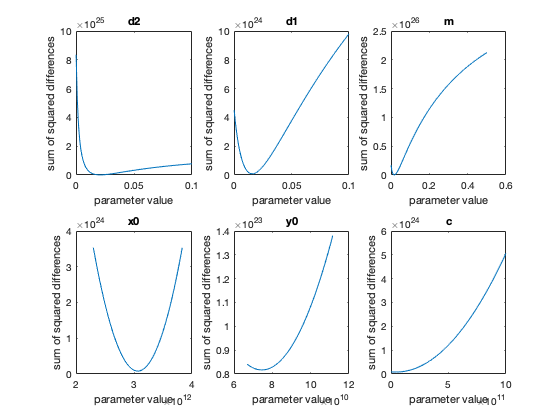



[parval, parres] = Profiles_lsq(lsqfun, xmulti, 100, lb, ub);
figure;
subplot(2,3,1)
plot(parval(1,:),parres(1,:));xlabel('parameter value');ylabel('sum of squared differences');title('d2');
subplot(2,3,2)
plot(parval(2,:),parres(2,:));xlabel('parameter value');ylabel('sum of squared differences');title('d1');
subplot(2,3,3)
plot(parval(3,:),parres(3,:));xlabel('parameter value');ylabel('sum of squared differences');title('m');
subplot(2,3,4)
plot(parval(4,:),parres(4,:));xlabel('parameter value');ylabel('sum of squared differences');title('x0');
subplot(2,3,5)
plot(parval(5,:),parres(5,:));xlabel('parameter value');ylabel('sum of squared differences');title('y0');
subplot(2,3,6)
plot(parval(6,:),parres(6,:));xlabel('parameter value');ylabel('sum of squared differences');title('c');

## %%% Function to determine features %%%%%

function [spac_days] = setSpacing(days, n_samples, distribution)
%Input:
%   days        amount of days in total
%   n_samples   amount of samples
%   distribution distritbution of the days, linear, log or log10

%Output:
%   spac_days   spacing of days

    if distribution == 1 %'linear'
        spacing = [0, linspace(0, days, n_samples-1)];
    elseif distribution == 2 % 'log10'
        spacing = [0, logspace(0, log10(days), n_samples-1)];
    elseif distribution == 3 %'log'
        spacing = [0, exp(linspace(1,log(days),n_samples-1))];
        
    end
    
    spac_days = round(spacing);
    
    for i = 1:(length(spac_days)-1)
        if spac_days(i) == spac_days(i+1)
            spac_days(i+1) = spac_days(i+1) + 1;
        end
    end
      
end 


function [sensitivity] = diff_integral(par,xdata,ydata,tspanX, tspanY)
%Calculates the differences between the data and simulation output
%can be used as input for lsqnonlin/least squares optimizer
%outputs:                          
%   sensitivity = output feature, differences of both outputs

%inputs:
%   tspan       timespan for integral
%   par =       adapted input parameters
%   data =      data vectors for x and y respectively

% determine output for adapted parameters
[x_out, y_out] = intLea(par, tspanX, tspanY);

%determine value of output of interest
featX = zeros(length(tspanX),1);
featY = zeros(length(tspanY),1);  

featX = (xdata - x_out); %calculate differences
featY = (ydata - y_out); %calculate differences

sensitivity = [featX, featY];

end 


function [negllh] = negLLH(par, xdata, ydata, tspanX, tspanY)
%calculates the negative log likelihood for minimization
%outputs:                          
%   sensitivity = output feature, squared difference of both outputs

%inputs:
%   tspan       timespan for integral
%   par =       adapted input parameters, including standard deviation
%   data =      data vectors for x and y respectively

% determine output for adapted parameters
[x_out, y_out] = intLea(par(1:6), tspanX, tspanY);

sigmX = par(7); 
sigmY = par(8);

%determine value of output of interest
featX = zeros(length(tspanX),1);
featY = zeros(length(tspanY),1);  

featX = (xdata - x_out); %calculate differences
featY = (ydata - y_out); %calculate differences

llhX = - 0.5 * log( 2 * pi * sigmX^2) - 0.5 * (featX.^2/sigmX^2);
llhY = - 0.5 * log( 2 * pi * sigmY^2) - 0.5 * (featY.^2/sigmY^2);
%http://jrmeyer.github.io/machinelearning/2017/08/18/mle.html

negllh = -1*(sum(llhX) + sum(llhY)) ; % possibility to apply weight factors

end 


function [x_out, y_out] = intLea(par, tspanX, tspanY)
% Integraded function, integration established by Lea
%Outputs:
%   time            time span used in the integral
%   x/y _out        output from integral for respectively x and y

%Input:
%   par             parameters for integral
%   tspan X/Y       time span for respectively x and y

d2 = par(1);
d1 = par(2);
m = par(3);
x0 = par(4);
y0 = par(5);
c = par(6);

A = d1*c;
B = (m+d1);

x_out = A/B + (x0 - A/B)*exp(-B*tspanX);

y_out = (m*A)/(B*d2) + ...
   ( m/(d2 - B) * (x0 - A/B)*exp(-B*tspanY) ) + ...
    (y0 - (m*A)/(B*d2) - (m/(d2 - B) * (x0 - A/B)))*exp(-d2 * tspanY);

end


function [parval, parres] = Profiles_llh(llhfun, par, num, lb, ub)
%calculate the likelihood for a certain parameter at num values between 
%the lb and the ub.

%Input:
%   llhfun      function handle of the likelihood function
%   par         optimized parameters
                                %  , parnum parnum      parameter to optimize
%   num         number of points to calculate in the profile
%   lb          lb of the problem
%   ub          ub of the problem

%Output:
%   parval      values of the parameter
%   parres      llh value for the parameter
    
% can also look into MATLAB profile function
    originalpar = par %save original parameters

    parnum = length(par);
    
    parres = zeros(parnum,num) ;
    parval = zeros(parnum,num) ;

    for j = 1:parnum
        
        parval(j,:) = linspace(lb(j), ub(j),num);
        
        for i = 1:num
            par(j) = parval(j,i);
            
            parres(j,i) = llhfun(par);
        end
        
        par = originalpar %reset to original input parameters
        
    end 
    
end


function [parval, parres] = Profiles_lsq(lsqfun, par, num, lb, ub)
%calculate the likelihood for a certain parameter at num values between 
%the lb and the ub.

%Input:
%   llhfun      function handle of the likelihood function
%   par         optimized parameters
                                %  , parnum parnum      parameter to optimize
%   num         number of points to calculate in the profile
%   lb          lb of the problem
%   ub          ub of the problem

%Output:
%   parval      values of the parameter
%   parres      llh value for the parameter
    
% can also look into MATLAB profile function
    originalpar = par; %save original parameters

    parnum = length(par);
    
    parres = zeros(parnum,num) ;
    parval = zeros(parnum,num) ;

    for j = 1:parnum
        
        parval(j,:) = linspace(lb(j), ub(j),num);
        
        for i = 1:num
            par(j) = parval(j,i);
            
            parres(j,i) = sum(lsqfun(par).^2);
        end
        
        par = originalpar; %reset to original input parameters
        
    end 

end